# **Mathematical Model of Neural Networks**

This live script will explain the mathematical details of neural nets. If you want to delve into deep learning or try to 

deploy a trained neural net on real-time hardware, you'll need to fully understand the mathematical model of neural

 nets. Let's use the following simple surface fitting task as an example:

$y=f\left(x_1 ,x_2 \right):R^2 \to R$, $y=x_1^2 +x_2^2$

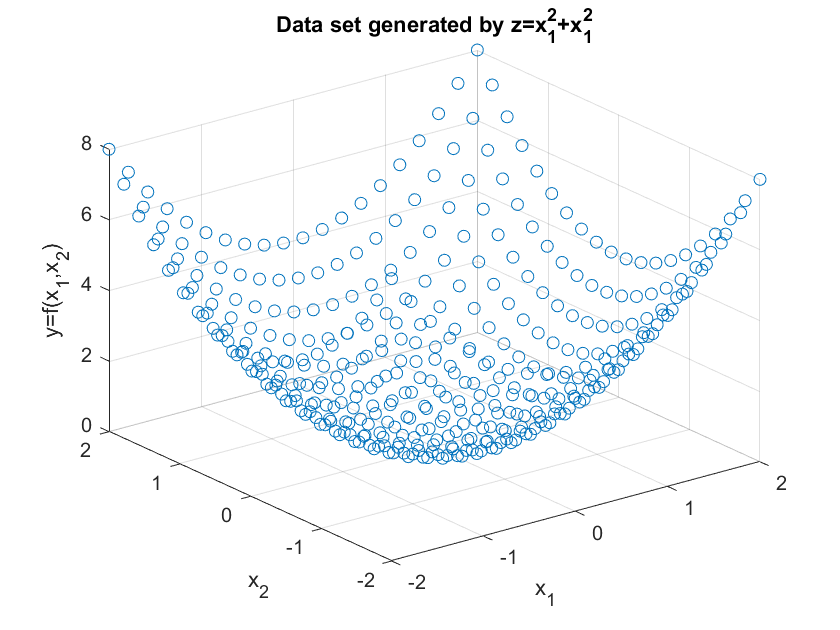

clear; clc; close all;
n=20; % number of sample
xspace=linspace(-2,2,n);
yspace=linspace(-2,2,n);
count=0;
for j=1:n
    for k=1:n
        count=count+1;
        Input(1,count)=xspace(j);
        Input(2,count)=yspace(k);
        zdata(count)=xspace(j)^2+yspace(k)^2;
    end
end

scatter3(Input(1,:),Input(2,:),zdata);
title('Data set generated by z=x_1^2+x_1^2')
xlabel('x_1'); ylabel('x_2'); zlabel('y=f(x_1,x_2)')

Set up a NN model and fit the surface.

% Model
InSize=2; OutSize=1;
LayerStruct=[InSize,3,4,OutSize];
NN=Initialization(LayerStruct);
% Optimization
option.MaxIteration=500;
NN=OptimizationSolver(Input,zdata,NN,option);

Iteration : 6 , Cost :       9.94737519 
Iteration : 12 , Cost :       8.10537685 
Iteration : 18 , Cost :       7.02178648 
Iteration : 24 , Cost :       5.61274380 
Iteration : 30 , Cost :       4.38092923 
Iteration : 36 , Cost :       3.45965940 
Iteration : 42 , Cost :       2.75883279 
Iteration : 48 , Cost :       2.23231355 
Iteration : 54 , Cost :       1.83361402 
Iteration : 60 , Cost :       1.53093901 
Iteration : 66 , Cost :       1.29806147 
Iteration : 72 , Cost :       1.11669107 
Iteration : 78 , Cost :       0.97720960 
Iteration : 84 , Cost :       0.86359519 
Iteration : 90 , Cost :       0.77149626 
Iteration : 96 , Cost :       0.69685306 
Iteration : 102 , Cost :       0.63645729 
Iteration : 108 , Cost :       0.58485018 
Iteration : 114 , Cost :       0.54238035 
Iteration : 120 , Cost :       0.50510861 
------------------------------------------------------
First Stage Optimization Finished in  125  Iteration.
------------------------------------------------

Now that we have a trained neural network, first, I'll present the formal mathematical expression of a neural net. 

Afterward, I'll use this trained NN to provide a step-by-step numerical example.

## Notations

**Bold** **alphabet** represent a vector or matrix.

$\mathit{\mathbf{x}}\in R^{N\times 1}$ : input variable, a $N\times 1$ column vector, where $N$ is the dimension of input data.

$\mathit{\mathbf{Y}}\in R^{M\times 1}$ : output of neural nets, a $M\times 1$ column vector, where $M$ is the dimension of output.

$\sigma :R^{\nu \;} \to R^{\nu \;}$ : activation, a point-wise nonlinear function, $\nu \in Z$ (arbitrary positive integer, depend on "`LayerStruct"`).

$d$: depth of neural nets, an integer scalar."

${\mathit{\mathbf{W}}}_k$: weight matrices, ${\mathit{\mathbf{b}}}_k$: bias vectors, $k=1,2,\ldotp \ldotp \ldotp ,d$

## Mathematics Representation of Neural Nets

( for regression/ surface fitting tasks)


$${\mathit{\mathbf{h}}}_0 =\mathit{\mathbf{x}}$$



$${\mathit{\mathbf{h}}}_{k+1} =\sigma \;\left({\mathit{\mathbf{W}}}_k {\mathit{\mathbf{h}}}_k +{\mathit{\mathbf{b}}}_k \right),k\in Z,k\le d$$



$$\mathit{\mathbf{y}}={\mathit{\mathbf{W}}}_d {\mathit{\mathbf{h}}}_{d-1} +{\mathit{\mathbf{b}}}_d$$



$$\mathit{\mathbf{y}}=\textrm{NN}\left(\mathit{\mathbf{x}}\right),\;\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^N \to R^M$$


## Accessing the parameters of trained neural nets.

Let's explain the above equation using our trained net.

What does this vector "`LayerStruct`" represent? The length of "`LayerStruct`" minus one determines the number 

of layers we would like to use in our neural network, and the numbers inside this vector specify the size of weight 

matrices and bias vectors for each layer.

depth=length(LayerStruct)-1

depth = 3

this imply we have $3$ weight matrice and bias vector, respectly, ${\mathit{\mathbf{W}}}_1 ,{\mathit{\mathbf{W}}}_2 ,{\mathit{\mathbf{W}}}_3$ and ${\mathit{\mathbf{b}}}_1 ,{\;\mathit{\mathbf{b}}}_{2,} \;{\;\mathit{\mathbf{b}}}_3$

you can access the parameters by typing:

W1=NN.weight{1} % W_1

W1 =    -0.0008   -0.0014
    0.0993   -0.0004
   -0.0003   -0.0864


W2=NN.weight{2} % W_2

W2 =     2.6755   -2.7118   -2.9578
    3.7312   -5.3970   -2.9859
   -1.8263    0.5928    4.2475
   -2.2167    1.6596    3.6502


b3=NN.bias{1} % b_1

b3 =     0.0012
   -0.0000
    0.0000


% and so on...

As for the point-wise nonlinear activation $\sigma \;\left(x\right)$, you can access it by typing:

acitve=NN.active

acitve = function_handle with value:
    @(x)exp(-x.^2)


the activation used in this net is just a Gaussian function, and the word "point-wise" means that:

                                                                          
$$\sigma \;\left(\left\lbrack \begin{array}{c}
\pi \;\\
0\\
2\ldotp 5
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
\sigma \left(\pi \;\right)\\
\sigma \left(0\right)\\
\sigma \left(2\ldotp 5\right)
\end{array}\right\rbrack$$


here's a numerical example:

DemoActive=NN.active([pi;0;2.5])

DemoActive =     0.0001
    1.0000
    0.0019


which is exactly the same using the following MATLAB command:

PointWiseMATLAB=exp(-[pi;0;2.5].^2)

PointWiseMATLAB =     0.0001
    1.0000
    0.0019


## A Step-by-Step Example

Let's demonstrate the step-by-step computation of a trained neural network. 

Our goal is to compute $\textrm{NN}\left(\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 5
\end{array}\right\rbrack \right)\approx {\left(0\ldotp 2\right)}^2 +{\left(0\ldotp 5\right)}^2 =0\ldotp 29$

Computation of first layer:


$${\mathit{\mathbf{h}}}_0 =\left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 5
\end{array}\right\rbrack$$



$${\mathit{\mathbf{h}}}_1 =\sigma \;\left({\mathit{\mathbf{W}}}_1 {\mathit{\mathbf{h}}}_0 +{\mathit{\mathbf{b}}}_1 \right)$$



$${\mathit{\mathbf{h}}}_1 =\sigma \;\left(\left\lbrack \begin{array}{cc}
w_{11}  & w_{12} \\
w_{21}  & w_{22} \\
w_{31}  & w_{32} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 5
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
\sigma \;\left({0\ldotp 2w}_{11} +{0\ldotp 5w}_{12} +b_1 \right)\\
\sigma \;\left({0\ldotp 2w}_{21} +0\ldotp 5w_{22} +b_2 \right)\\
\sigma \;\left({0\ldotp 2w}_{31} +0\ldotp 5w_{32} +b_3 \right)
\end{array}\right\rbrack$$


Note that, the demonstration below will use $w_{\textrm{ij}} ,b_i$ repeatly (easy to type), 

**this doesn't meant that** ${\mathit{\mathbf{W}}}_1 ,{\mathit{\mathbf{W}}}_2 ,{\mathit{\mathbf{W}}}_3$ **and** ${\mathit{\mathbf{b}}}_1 ,{\;\mathit{\mathbf{b}}}_{2,} {\;\mathit{\mathbf{b}}}_3$ **share the same parameters**.

h0=[0.2;0.5];
h1=NN.active(NN.weight{1}*h0+NN.bias{1}) % h1=sigma(W1*h0+b1)

h1 =     1.0000
    0.9996
    0.9981


Computation of second layer:


$${\mathit{\mathbf{h}}}_2 =\sigma \;\left({\mathit{\mathbf{W}}}_2 {\mathit{\mathbf{h}}}_1 +{\mathit{\mathbf{b}}}_2 \right)$$



$${\mathit{\mathbf{h}}}_2 =\sigma \;\left(\left\lbrack \begin{array}{ccc}
w_{11}  & w_{12}  & w_{12} \\
w_{21}  & w_{22}  & w_{23} \\
w_{31}  & w_{32}  & w_{33} \\
w_{41}  & w_{42}  & w_{43} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\ldotp 0000\\
0\ldotp 9996\\
0\ldotp 9981
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 \\
b_4 
\end{array}\right\rbrack \right)$$


h2=NN.active(NN.weight{2}*h1+NN.bias{2}) % h2=sigma(W2*h1+b2)

h2 =     0.7993
    0.3488
    0.3243
    0.5594


Computation of third layer (last layer):

Note that, for regression task (surface fitting), the nonlinear activation $\sigma \;$will not act on last layer,

just simple matrix multiplication. (linear transform)


$$z={\mathit{\mathbf{W}}}_3 {\mathit{\mathbf{h}}}_2 +{\mathit{\mathbf{b}}}_3$$



$$z=\left\lbrack \begin{array}{cccc}
w_{11}  & w_{12}  & w_{13}  & w_{14} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\ldotp 7898\\
0\ldotp 3476\\
0\ldotp 3325\\
0\ldotp 5549
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
b_1 
\end{array}\right\rbrack$$


z=NN.weight{3}*h2+NN.bias{3} % y=W3*h2+b3

z = 0.2937

zTrue=(0.2)^2+(0.5)^2

zTrue = 0.2900

you can observe that the output of this net match quite well to the real $f\left(x_1 ,x_2 \right)=x_1^2 +x_2^2$ function.

The above computation can be done automatically using the command "`NN.Evaluate`".

NN.Evaluate([0.2;0.5])

ans = 0.2937

Compact form:

                                        
$$\begin{array}{l}
{\mathit{\mathbf{h}}}_0 =\mathit{\mathbf{x}}\\
{\mathit{\mathbf{h}}}_1 =\sigma \;\left({\mathit{\mathbf{W}}}_1 {\mathit{\mathbf{h}}}_0 +{\mathit{\mathbf{b}}}_1 \right)\\
{\mathit{\mathbf{h}}}_2 =\sigma \;\left({\mathit{\mathbf{W}}}_2 {\mathit{\mathbf{h}}}_1 +{\mathit{\mathbf{b}}}_2 \right)\\
y={\mathit{\mathbf{W}}}_3 {\mathit{\mathbf{h}}}_2 +{\mathit{\mathbf{b}}}_3 
\end{array}$$


## **Preprocessing of Data Set**

preprocess can play an important role for training neural nets, without proper preprocess, optimization solvers may fail to converge or

produce unsatisfy results.The pack has a simple preprocess method : Normalization.

If you're familiar with preprocessing method, you can just ignore this part, the full computation of a neural net is

state in previous section.

if not, use `"NN.InputAutoScaling"` or `"NN.LabelAutoScaling" `function to perform basic normalization.

% NN.InputAutoScaling='on'; 
% NN.LabelAutoScaling='on';

As for when to use the above function, please refer to "`TipsForTrainingNeuralNet.mlx`".

What's normalization? take this simple data set as example,

                                
$$y=f\left(x\right)=\sin \left(x\right),x\in \left\lbrack 0,2\pi \right\rbrack$$


Note that, this data set is just for demostration, preprocessing doesn't matter in this case. 

x=linspace(0,2*pi,10); y=sin(x);

normalization formula:

let $x^{\prime }$ denote as normalized data, then

$x^{\prime } =\frac{x-\mu_x \;}{\sigma_x \;}\;$, where $\mu_x \;$and $\sigma_x \;$ are mean and standard deviation of data $x$.

before normalization:

x

x =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832


after normalization:

xNormalized=(x-mean(x))/std(x)

xNormalized =    -1.4863   -1.1560   -0.8257   -0.4954   -0.1651    0.1651    0.4954    0.8257    1.1560    1.4863


This normalization formula is the same for output data $y$:

                                        
$$y^{\prime } =\frac{y-\mu_y }{\sigma {\;}_y }$$


## Computation Model After Applying Auto-Scaling

Let's train a net with Auto-scaling.

% Using same structure but with autoscaling
NN.InputAutoScaling='on';
NN.LabelAutoScaling='on';
NN=Initialization(LayerStruct,NN);
% Optimization
NN=OptimizationSolver(Input,zdata,NN,option);

Iteration : 6 , Cost :       2.18188716 
Iteration : 12 , Cost :       1.80219489 
Iteration : 18 , Cost :       1.63155245 
Iteration : 24 , Cost :       1.45637042 
Iteration : 30 , Cost :       1.27144338 
Iteration : 36 , Cost :       1.08725355 
Iteration : 42 , Cost :       0.90683855 
Iteration : 48 , Cost :       0.74076780 
Iteration : 54 , Cost :       0.59642583 
Iteration : 60 , Cost :       0.47958913 
Iteration : 66 , Cost :       0.38758831 
Iteration : 72 , Cost :       0.31707749 
Iteration : 78 , Cost :       0.26395195 
Iteration : 84 , Cost :       0.22276403 
Iteration : 90 , Cost :       0.19069142 
Iteration : 96 , Cost :       0.16476271 
Iteration : 102 , Cost :       0.14371647 
Iteration : 108 , Cost :       0.12578312 
Iteration : 114 , Cost :       0.11033292 
Iteration : 120 , Cost :       0.09648895 
------------------------------------------------------
First Stage Optimization Finished in  125  Iteration.
------------------------------------------------

If you set `NN.InputAutoScaling='on' `or  `NN.LabelAutoScaling='on';`

`"NN.Evaluate"` will perform following linear transform to compensate normalization, the linear transform is used to 

ensure that the data is properly scaled and restored to its original range after normalization.

Again, $\mathit{\mathbf{x}}$ represents your original input data before normalization, ${\mathit{\mathbf{h}}}_d$ is the original output of the nerual net (before 

normalization), and $\mathit{\mathbf{y}}$ is the real output of the network.

$\odot$ represents point-wise multiplication.


$${\mathit{\mathbf{h}}}_0 =\left\lbrace \begin{array}{ll}
{\mathit{\mathbf{s}}}_1 \odot \mathit{\mathbf{x}}-{\mathit{\mathbf{c}}}_1  & ,\;\mathrm{InputAutoScaling}=\mathrm{on}\\
\mathit{\mathbf{x}} & ,\;\mathrm{InputAutoScaling}=\mathrm{off}
\end{array}\right.$$
  


$${\mathit{\mathbf{h}}}_{k+1} =\sigma \;\left({\mathit{\mathbf{W}}}_k {\mathit{\mathbf{h}}}_k +{\mathit{\mathbf{b}}}_k \right)$$



$${\mathit{\mathbf{h}}}_d ={\mathit{\mathbf{W}}}_d {\mathit{\mathbf{h}}}_{d-1} +{\mathit{\mathbf{b}}}_d$$



$$\mathit{\mathbf{y}}=\left\lbrace \begin{array}{ll}
{\mathit{\mathbf{s}}}_2 \odot \;{\mathit{\mathbf{h}}}_d +{\mathit{\mathbf{c}}}_2  & ,\mathrm{Label}\mathrm{AutoScaling}=\mathrm{on}\\
{\mathit{\mathbf{h}}}_d  & ,\mathrm{LabelAutoScaling}=\mathrm{off}
\end{array}\right.$$


The computation is almost the same as in the previous section. 

You can obtain the parameters ${\mathit{\mathbf{s}}}_1 ,{\mathit{\mathbf{c}}}_1 ,{\mathit{\mathbf{s}}}_2 ,{\mathit{\mathbf{c}}}_2$ by typing:

s1=NN.InputScaleVector

s1 =     0.8227
    0.8227


c1=NN.InputCenterVector

c1 = 	1.0e+-16 *

   -0.2923
    0.0228


s2=NN.LabelScaleVector

s2 = 1.8594

c2=NN.LabelCenterVector

c2 = 2.9474

We'll demonstrate the computation of a neural net with auto-scaling again.

same goal : compute $\mathrm{NN}\left(\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 5
\end{array}\right\rbrack \right)\approx {\left(0\ldotp 2\right)}^2 +{\left(0\ldotp 5\right)}^2 =0\ldotp 29$

Computation of first layer:


$${\mathit{\mathbf{h}}}_0 ={\mathit{\mathbf{a}}\odot \;\mathit{\mathbf{x}}}_0 -\mathit{\mathbf{b}}$$



$${\mathit{\mathbf{h}}}_0 =\left\lbrack \begin{array}{c}
0\ldotp 8227\\
0\ldotp 8227
\end{array}\right\rbrack \odot \left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-0\ldotp 2923\times {10}^{-16} \\
0\ldotp 0183\times {10}^{-16} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 8227\times 0\ldotp 2-\left(-0\ldotp 2923\times {10}^{-16} \right)\\
0\ldotp 8227\times 0\ldotp 5-\left(0\ldotp 0183\times {10}^{-16} \right)
\end{array}\right\rbrack$$


h0=a.*[0.2;0.5]-b % a.*x-b

h0 =     0.1645
    0.4114



$${\mathit{\mathbf{h}}}_1 =\sigma \;\left({\mathit{\mathbf{W}}}_1 h_0 +{\mathit{\mathbf{b}}}_1 \right)$$



$${\mathit{\mathbf{h}}}_1 =\sigma \;\left(\left\lbrack \begin{array}{cc}
w_{11}  & w_{12} \\
w_{21}  & w_{22} \\
w_{31}  & w_{32} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\ldotp 1645\\
0\ldotp 4114
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
\sigma \;\left({0\ldotp 1645w}_{11} +{0\ldotp 4114w}_{12} +b_1 \right)\\
\sigma \;\left({0\ldotp 1645w}_{21} +0\ldotp 4114w_{22} +b_2 \right)\\
\sigma \;\left({0\ldotp 1645w}_{31} +0\ldotp 4114w_{32} +b_3 \right)
\end{array}\right\rbrack$$


h1=NN.active(NN.weight{1}*h0+NN.bias{1}) % h1=sigma(W1*h0+b1)

h1 =     0.9999
    0.9936
    0.9892


Computation of second layer:


$${\mathit{\mathbf{h}}}_2 =\sigma \;\left({\mathit{\mathbf{W}}}_2 {\mathit{\mathbf{h}}}_1 +{\mathit{\mathbf{b}}}_2 \right)$$



$${\mathit{\mathbf{h}}}_2 =\sigma \;\left(\left\lbrack \begin{array}{ccc}
w_{11}  & w_{12}  & w_{12} \\
w_{21}  & w_{22}  & w_{23} \\
w_{31}  & w_{32}  & w_{33} \\
w_{41}  & w_{42}  & w_{43} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\ldotp 9999\\
0\ldotp 9936\\
0\ldotp 9892
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 \\
b_4 
\end{array}\right\rbrack \right)$$


h2=NN.active(NN.weight{2}*h1+NN.bias{2}) % h2=sigma(W2*h1+b2)

h2 =     0.3081
    0.4180
    0.7658
    0.1853


Computation of third layer (last layer):


$$h_3 ={\mathit{\mathbf{W}}}_3 {\mathit{\mathbf{h}}}_2 +{\mathit{\mathbf{b}}}_3$$



$$h_3 =\left\lbrack \begin{array}{cccc}
w_{11}  & w_{12}  & w_{13}  & w_{14} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\ldotp 3081\\
0\ldotp 4180\\
0\ldotp 7658\\
0\ldotp 1853
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
b_1 
\end{array}\right\rbrack$$


h3=NN.weight{3}*h2+NN.bias{3} % y=W3*h2+b3

h3 = -1.4249


$$y=c\odot h_3 +d$$



$$\;\;=$$

$$\left\lbrack \begin{array}{c}
1\ldotp 8594\odot -1\ldotp 4249
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
2\ldotp 9474
\end{array}\right\rbrack =1\ldotp 8594\times \left(-1\ldotp 4249\right)+2\ldotp 9474$$


z=c.*h3+d % z=c.*h3+d

z = 0.2979

Compact form:

                                        
$$\begin{array}{l}
{\mathit{\mathbf{h}}}_0 ={\mathit{\mathbf{s}}}_1 \odot \mathit{\mathbf{x}}-{\mathit{\mathbf{c}}}_1 \\
{\mathit{\mathbf{h}}}_1 =\sigma \;\left({\mathit{\mathbf{W}}}_1 {\mathit{\mathbf{h}}}_0 +{\mathit{\mathbf{b}}}_1 \right)\\
{\mathit{\mathbf{h}}}_2 =\sigma \;\left({\mathit{\mathbf{W}}}_2 {\mathit{\mathbf{h}}}_1 +{\mathit{\mathbf{b}}}_2 \right)\\
h_3 ={\mathit{\mathbf{W}}}_3 {\mathit{\mathbf{h}}}_2 +{\mathit{\mathbf{b}}}_3 \\
y=s_2 \odot h_3 +c_2 
\end{array}$$
